clc
clear all

img = uint16(imread('final_com.tif')); %Image date: 26-12-2020
FCC_before_PCA = cat(3, img(:,:,5), img(:,:,4), img(:,:,3)); %NIR(5) RED(4) GREEN(3)

FCC_before_PCA = imlocalbrighten(FCC_before_PCA); %Histogam stretching

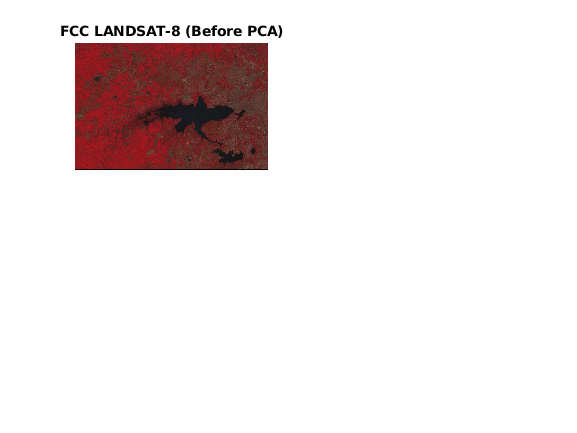

subplot(221)
imshow((FCC_before_PCA))
title('FCC LANDSAT-8 (Before PCA)')

[r c] = size(img(:,:,1)); %Preserving the shape
for i = 1:11
    shape_img = reshape(img(:,:,i),[],1); %Converting each band into a column vector
    shape_final_data(:,i)=shape_img;
end

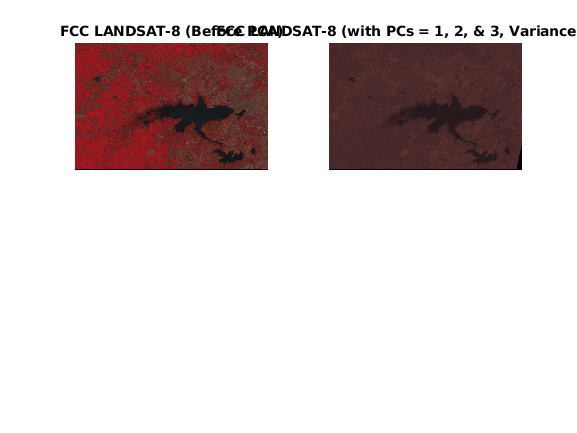

subplot(222)
nComp = 1; %input('Please enter the no. of PCs: \n')
shape_final_data = double(shape_final_data);
shape_final_data_m = mean(shape_final_data);
shape_final_data_m_adjusted = (shape_final_data - shape_final_data_m);
[coeff, score, latent, ~, explained] = pca(shape_final_data_m_adjusted);

%The next two statements forms the formula for reconstruction of the data
reconstruction_data = score(:, 1:nComp)*coeff(:, 1:nComp)';
final_reconstruction = (reconstruction_data + shape_final_data_m);
for i = 1:11
    Reconstructed_final = reshape(final_reconstruction(:, i), r, c);
    img_final(:, :, i) = Reconstructed_final;
end
img_final = uint16(img_final);
FCC_after_PCA = cat(3, img_final(:, :, 5), img_final(:, :, 4), img_final(:, :, 3));
FCC_after_PCA = imlocalbrighten(FCC_after_PCA);
imshow((FCC_after_PCA))
title('FCC LANDSAT-8 (with PCs = 1, 2, & 3, Variance = 95%)')